% Task 2b: Brief Analysis of the Given Systems

% Clear the workspace and command window
clear; clc;

%% System 1: G1(s) = 10 / (s^3 + 5.8*s^2 + 8*s + 20)
% Define the transfer function G1(s)
num1 = 10;   % Numerator
den1 = [1 5.8 8 20]; % Denominator coefficients
G1 = tf(num1, den1);

% Analyze System 1
fprintf('System 1: G1(s)\n');

System 1: G1(s)


% Poles
poles_G1 = pole(G1);
zeroes_G1 = zero(G1)


zeroes_G1 =

  0×1 empty double column vector



fprintf('Poles of G1: \n');

Poles of G1: 


disp(poles_G1);

  -5.0000 + 0.0000i
  -0.4000 + 1.9596i
  -0.4000 - 1.9596i



disp(zeroes_G1);

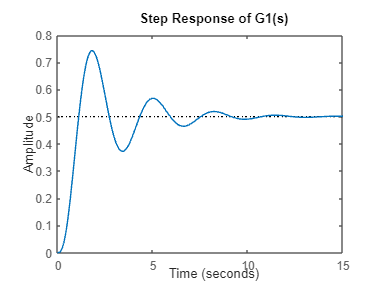


% Step Response
figure;
step(G1);
title('Step Response of G1(s)');

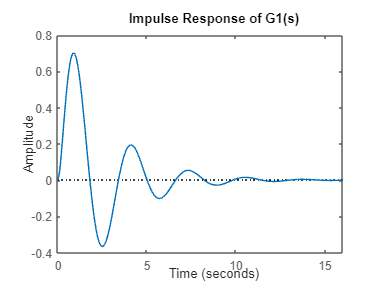

% Impulse Response
figure;
impulse(G1);
title('Impulse Response of G1(s)');

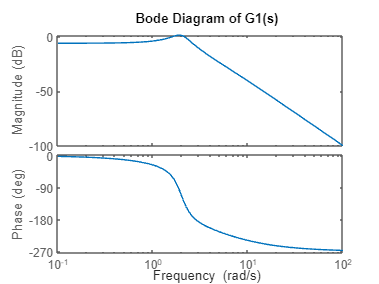

% Bode Diagram
figure;
bode(G1);
title('Bode Diagram of G1(s)');

%% Discretization using Tustin's method
Ts = 0.1;  % Sampling time (you can change this based on your requirement)

% Discrete transfer function using Tustin (bilinear) transformation
G1_discrete = c2d(G1, Ts, 'tustin');

fprintf('Discrete-time transfer function using Tustin method:\n');

Discrete-time transfer function using Tustin method:


G1_discrete

G1_discrete =
 
  0.0009524 z^3 + 0.002857 z^2 + 0.002857 z + 0.0009524
  -----------------------------------------------------
           z^3 - 2.486 z^2 + 2.055 z - 0.5543
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


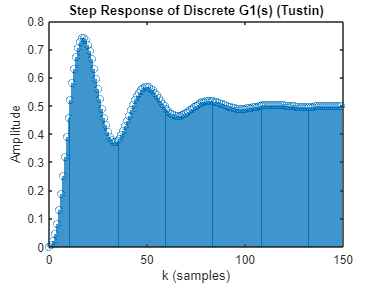

[y_step, t_step] = step(G1_discrete);  % Get the step response and corresponding time vector

figure;
k = 0:length(t_step)-1;  % Generate sample indices (k)
stem(k, y_step, 'filled');  % Use stem plot to show discrete points
xlabel('k (samples)');
ylabel('Amplitude');
title('Step Response of Discrete G1(s) (Tustin)');